# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

clear;
clc;
close all;

## put your code Here

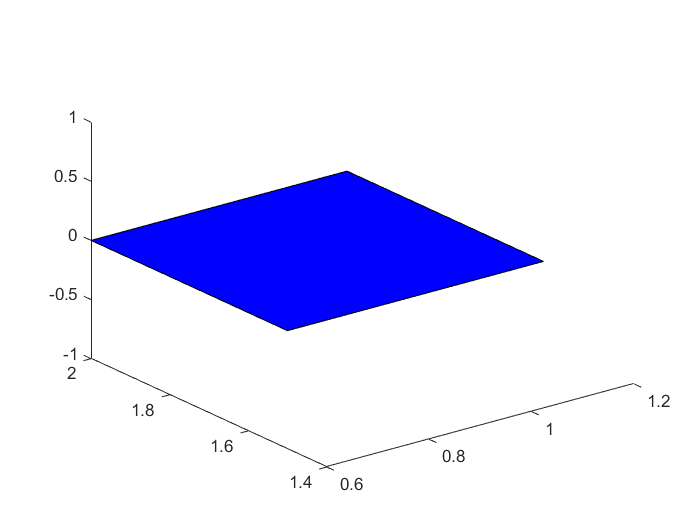

% Crate the tool table 
TX1 = [0.6 0.6 1.1 1.1];
TY1 = [2 1.5 1.5 2];
TZ1 = [0 0 0 0];
toolTable = fill3(TX1,TY1,TZ1,'b');

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

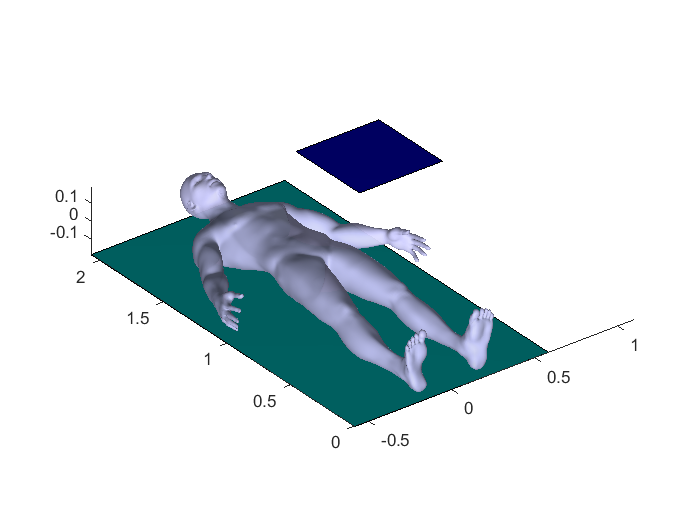

%% put your code Here
HumanBody = load("Model\F_V_Human_Body.mat");
HumanBody.V = HumanBody.V/10;
patch('Faces', HumanBody.F, 'Vertices', HumanBody.V,...
      'FaceColor',[0.8 0.8 1.0],...
      'EdgeColor','none',...
      'FaceLighting',    'gouraud',     ...
      'AmbientStrength', 0.8,'FaceAlpha', 0.8);
camlight('headlight');
material('dull');
axis equal
hold on;
% Find the bounding box of the human body to create the operating table 
humanXmax = max(HumanBody.V(:, 1));
humanXmin = min(HumanBody.V(:, 1));
humanYmax = max(HumanBody.V(:, 2));
humanYmin = min(HumanBody.V(:, 2));
humanZmax = max(HumanBody.V(:, 3));
humanZmin = min(HumanBody.V(:, 3));
TX2 = [humanXmin humanXmin humanXmax humanXmax];
TY2 = [humanYmin humanYmax humanYmax humanYmin];
TZ2 = [humanZmin humanZmin humanZmin humanZmin];
opTable = fill3(TX2,TY2,TZ2,'c');

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

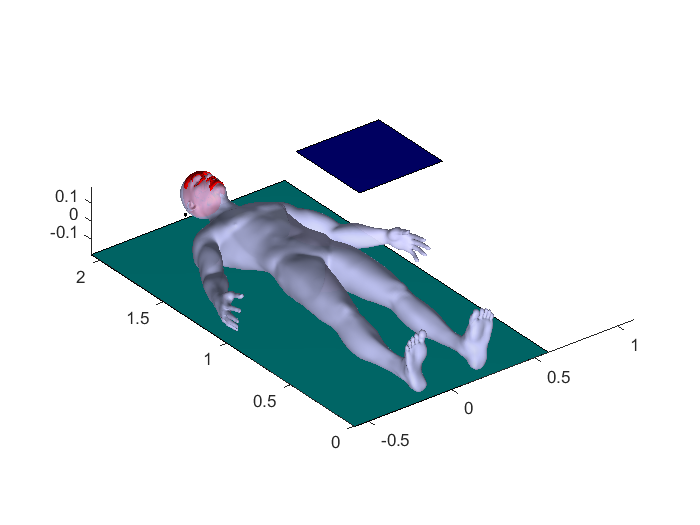

%% put your code Here
Skull = load("Model\F_V_N_Skull.mat");
Vertices = Skull.Ve/125; 
Vertices = [Vertices'; ones(1, size(Vertices,1))];
Vertices = transl(0, 1.83, 0)*trotx(-pi/2)*Vertices;
Vertices = Vertices(1:3,:);
Vertices = Vertices';
patch('Faces', Skull.Fa, 'Vertices', Vertices,...
      'FaceColor', 'red' ,...
      'EdgeColor','none');
material('dull');
axis equal

% ------------ Fiducials ----------------
scale = 1/800;

fiducials = [213 73 32; 213 185 65; 213 122 94];
fiducials = fiducials*scale;
fiducials = [fiducials'; ones(1, size(fiducials,1))];
transformacionImg = transl(0.15, 1.9, 0.165)*trotx(-pi/2)*trotz(pi/2);
fiducials = transformacionImg*fiducials;
fiducials = fiducials(1:3,:);
fiducials = fiducials';

scaleSphere = 1/150;

[X1, Y1, Z1] = sphere;
X1 = X1*scaleSphere+fiducials(1,1); Y1 = Y1*scaleSphere+fiducials(1,2); 
Z1 = Z1*scaleSphere+fiducials(1,3);
surf(X1,Y1,Z1);

[X2, Y2, Z2] = sphere;
X2 = X2*scaleSphere+fiducials(2,1); Y2 = Y2*scaleSphere+fiducials(2,2); 
Z2 = Z2*scaleSphere+fiducials(2,3);
surf(X2,Y2,Z2);

[X3, Y3, Z3] = sphere;
X3 = X3*scaleSphere+fiducials(3,1); Y3 = Y3*scaleSphere+fiducials(3,2);
Z3 = Z3*scaleSphere+fiducials(3,3);
surf(X3,Y3,Z3);

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

% put your code Here
points = double.empty(0,3);
%figure;
for i = 65:89
    path = cat(2,['DICOM\IMG00'], num2str(i),['.dcm']);
    I = dicomread(path);
    %imshow(I, [])
    BW = imbinarize(mat2gray(I),'adaptive');
    %imshow(BW, [])
    %imshow(filtered, [])
    R = regionprops(BW, 'PixelList','PixelIdxList');
    for j = 1:size(R)
        if ~ismember([129,95],R(j).PixelList,'rows')
            BW(R(j).PixelIdxList) = 0;
        end
    end
    %imshow(filtered)
    se = strel('disk', 3);
    filtered = imopen(BW, se);
    filtered = bwareafilt(filtered,1);
    filtered = imfill(filtered,'holes');
    se = strel('disk', 5);
    filtered = imclose(filtered, se);
    perimetre = bwperim(filtered);
    %imshow(perimetre);
    %imshow(imoverlay(mat2gray(I),perimetre,'yellow'));
    %drawnow;
    %pause(0.1)
    R = regionprops(filtered,'PixelList');
    for j = 1:size(R.PixelList)
        points = [points; [R.PixelList(j,2) R.PixelList(j,1) i]];
    end
    %points = [points; 
end
points = points*scale;
T_P_Img = mean(points);
points = [points'; ones(1, size(points,1))];
points = transformacionImg*points;
points = points(1:3,:);
p = points';


scatter3(p(:,1),p(:,2),p(:,3),1) 
axis equal
axis tight

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

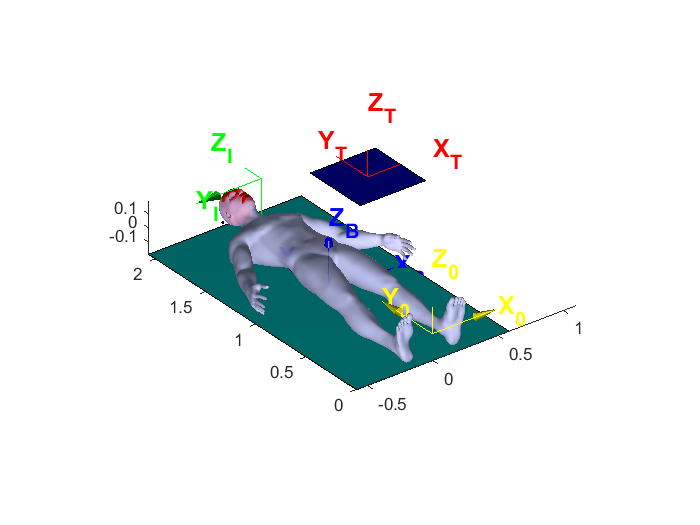

%% put your code Here
length = 0.5;
width = 1.5;
% origin (0,0,0)
Z = transl(0,0,0); 
trplot(Z, ... 
        'frame', '0', ... 
        'color', 'y',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);
    
% Image
%I = transl(mean(points(:,1)),mean(points(:,2)),mean(points(:,3)));
I = transformacionImg;
trplot(I, ... 
        'frame', 'I', ... 
        'color', 'g',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);
    
% Body Table 
BT = transl(mean(TX2), mean(TY2), mean(TZ2));
trplot(BT, ... 
        'frame', 'B', ... 
        'color', 'b',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);

% Tool Table 
TT = transl(mean(TX1), mean(TY1), mean(TZ1));
trplot(TT, ... 
        'frame', 'T', ... 
        'color', 'r',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Place robot near the human body (+0.8 in Y with respect to the crane) , and set the tool to 45 degrees with longitudinal axis of the human body (Y axis), and rotate the robot 3pi/2 to make the tool point to the tumor.*

*Plot the Robot and reference frame of the respective Base {R} and End Effector {E}.*

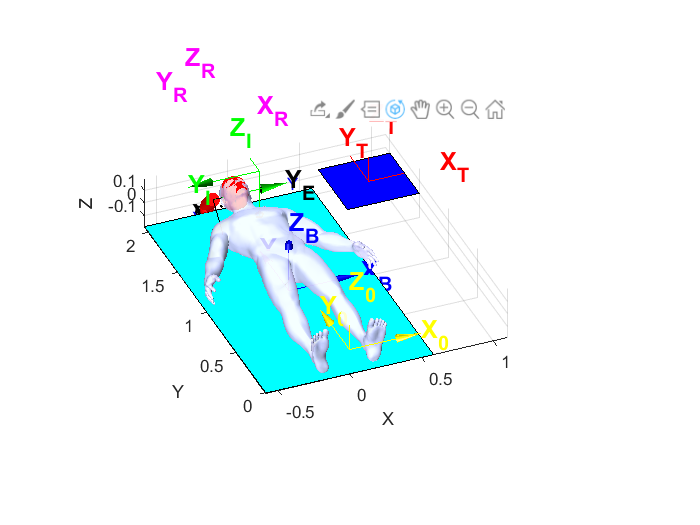

mdl_puma560
p560.base = transl(0, 2.8, 0);
p560.tool = transl(0,0,0.25)*troty(45, 'deg');
q = qn;
q(1) = 3*pi/2; 
p560.plot(q);

% End Efector
E = p560.fkine(q);
trplot(E, ... 
        'frame', 'E', ... >
        'color', 'k',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);
    
% Robot Base
R = p560.base;
trplot(R, ... 
        'frame', 'R', ... 
        'color', 'm',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);

set(gca, 'CameraTarget', [0.5, 1 ,0]);
set(gca, 'CameraPosition', [-4,-10, 8])

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

Etrasl = E.t;
Eeul = E.toeul;
T = SE3(transformacionImg);
Ttrasl = T.t;
Teul = T.toeul;
T_T_R = transl(Ttrasl-Etrasl)*eul2tr(Teul-Eeul)*inv(transformacionImg);

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

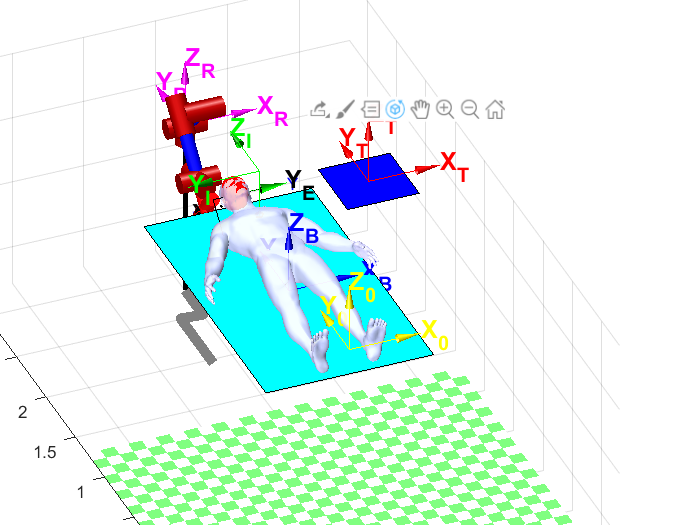

p = [points; ones(1, size(points,2))];
p = T_T_R*p;
p = p(1:3,:);
p = points';
scatter3(p(:,1),p(:,2),p(:,3),2)    
axis equal
axis tight

9.- Prepare a script that perform a biopsy. Zoom in the scene

*with the tool at 45 degrees, make a hole at the patients skull in a circlic shape (like the tumor size) and then make the biopsy slowly in a straight movement.*

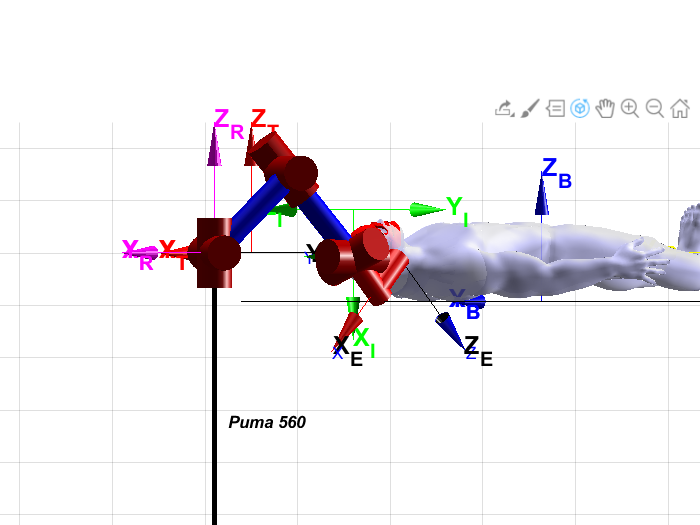

set(gca, 'CameraTarget', [-2,4,0]);
set(gca, 'CameraPosition', [-8,10,0]);
t = [0:0.05:2]'; %from 0 to 2s, each step 0.05s
T0 = E.T;
TF = transl(mean(p)); TF(3) = TF(3) + 0.5;
Qn1 = p560.jtraj(T0, TF, t);
Qn2 = p560.jtraj(TF, T0, t);
Qn = [Qn1; Qn2];
p560.plot(Qn);

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here


11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here


12.-Modify your code  to repeat point from 7 till 11 if ZX plane of the Robot is not aligned with the plane of symmetry of the human body. There is a free rotation among these two planes. 

*See: * *‘Sckeching_Key_ideas_students.mlx’ and ‘Triangles_2.mlx’ for inspiration.*

*Add your comemnts here.....be concise*

%% put your code Here